# Question 5

clear
clc
close all

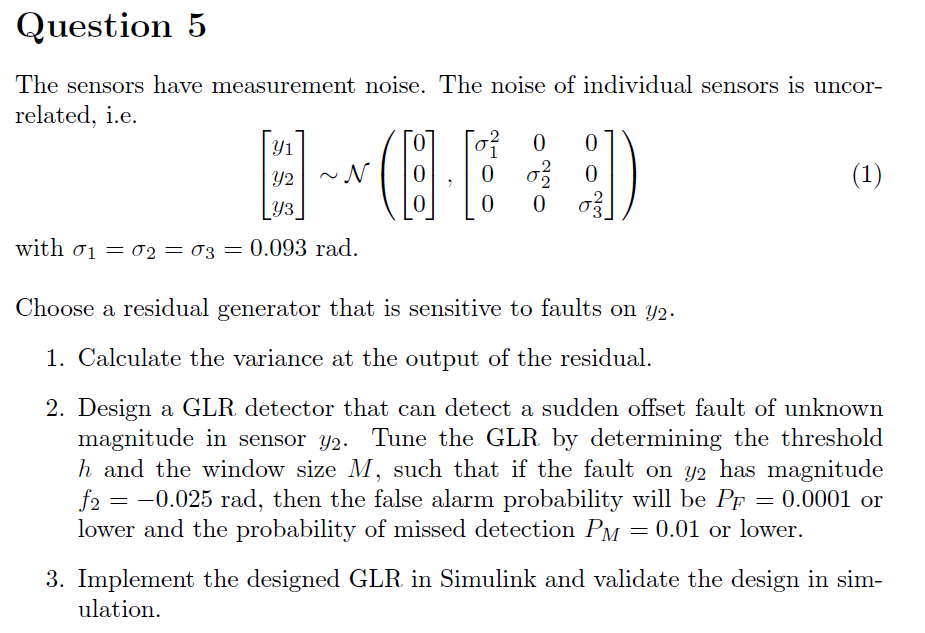

load res_tf.mat
load r3r4.mat

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

% Load data
load ECP502Data.mat



## System

% A = [0, 1, 0, 0, 0, 0; 
%     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0; 
%     0,0,0, 1,0,0; 
%     k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0; 
%     0,0,0,0,0,1; 
%     0,0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];
% 
% B = [0,0;
%     1/J_1, 0; 
%     0,0; 
%     0,1/J_2; 
%     zeros(2)];
% 
% C = [1, zeros(1,5); 0,0,1,zeros(1,3); zeros(1,4), 1, 0]; 
% D = zeros(3,2); 
% Ex = [0; -1/J_1; zeros(4,1)]; 
% Ey = zeros(3,1);

## Question 1

SIM_TIME = 100;
STEP_SIZE = 0.001;

sys = linearize('q5_VAR');

disp("A:"); disp(sys.A)

A:
   -3.6000   -2.0000         0         0
    2.0000         0         0         0
         0         0   -3.6000   -2.0000
         0         0    2.0000         0



disp("B:"); disp(sys.B)

B:
     0     2     0
     0     0     0
     0     0     2
     0     0     0



disp("C:"); disp(sys.C)

C:
         0   -2.5339   -0.0128    2.5266



disp("D:"); disp(sys.D)

D:
         0         0    0.0073




A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;


Solve Lyapunov equation


$$\textrm{AQ}+{\textrm{QA}}^T +{\textrm{BS}}_v B^T =0$$


syms q11 q12 q13 q14 q22 q23 q24 q33 q34 q44

Q = [q11, q12, q13, q14;
     q12, q22, q23, q24;
     q13, q23, q33, q34;
     q14, q24, q34, q44];

% Sv = sigma_meas(1,1)^2;
Sv = 0.0093^2*eye(3);

% Lyapunov
eq1 = 0 == A*Q + Q*(A.') + B*Sv*(B.');

sol = vpasolve(eq1,[q11 q12 q13 q14 q22 q23 q24 q33 q34 q44]);

q11 = sol.q11;
q12 = sol.q12;
q13 = sol.q13;
q14 = sol.q14;
q22 = sol.q22;
q23 = sol.q23;
q24 = sol.q24;
q33 = sol.q33;
q34 = sol.q34;
q44 = sol.q44;

Q = double([q11, q12, q13, q14;
     q12, q22, q23, q24;
     q13, q23, q33, q34;
     q14, q24, q34, q44]);

disp("Variance of r2:")

Variance of r2:


disp(C*Q*(C.'))

   6.1525e-04




disp("Std of r2:")

Std of r2:


disp(sqrt(C*Q*(C.')))

    0.0248




sigma_r2 = sqrt(C*Q*(C.'));

Variance and std of residual r2 is


$$\begin{array}{l}
\sigma {\;}_{\textrm{r2}}^2 =6\ldotp 153*{10}^{-4} \\
\sigma {\;}_{\textrm{r2}} =0\ldotp 0248
\end{array}$$



% f_m = [0;-0.025;0]; f_m_time = 10;
% 
% 
% SIM_TIME = 1000;
% STEP_SIZE = 0.001;
% t = 0:STEP_SIZE:SIM_TIME;
% n_t = length(t);
% 
% % Inputs
% u1 = zeros(n_t,1);
% u2 = zeros(n_t,1);
% U = [t', u1, u2];
% 
% seed = 80;
% 
% % Simulation
% out = sim('q5_VAR.slx', SIM_TIME, [], U);
% 
% % % Residuals
% r = out.r.Data;
% r1 = r(:,1);
% r2 = r(:,2);
% r3 = r(:,3);
% r4 = r(:,4);
% t_d = out.r.Time;
% 
% sigma_r2 = var(r2);
% 
% fprintf('Variance of residual r2: %f\n', sigma_r2);


## Question 2: h and M

syms h lambda x

assume(h, 'positive');
P_F = 0.0001; % false alarm probability
P_M = 0.01; % missed detection probability

f = 1/(sqrt(2) * gamma(1/2)) * x^(-1/2) * exp(-x/2);
h_f = int(f, x, 2*h, Inf);
eq = P_F - h_f == 0;
h_sol = double(vpasolve(eq, h, [0, 1000]));
fprintf('h = %f\n', h_sol);

h = 7.568353



sigma_y2 = 0.0093;
mu_1 = -0.025;

P_D = 1-P_M;
lambda = fzero(@(lambda) ncx2cdf(2*h_sol, 1, lambda) - P_D, 5);
M = ceil(lambda/((mu_1 - 0)^2/sigma_r2))

M = 98


h = h_sol;

## Question 2: simulation

f_m = [0;-0.025;0]; f_m_time = 10;


SIM_TIME = 50;
STEP_SIZE = 0.001;
t = 0:STEP_SIZE:SIM_TIME;
n_t = length(t);


% Inputs
u1 = zeros(n_t,1);
u1(t>5) = 1;
% u1(t>45) = 0;
% u1(t>35) = -1;
u2 = zeros(n_t,1);
u2(t>30) = 1;
% u2(t>20) = 0;
% u2(t>30) = -1;
U = [t', u1, u2];

% Simulation
out = sim('q5_TDO.slx', SIM_TIME, [], U);

Error due to multiple causes.

Caused by:
    Error using q5 (line 176)
    Invalid setting for output port dimensions of 'q5_TDO/Plant with sensors/Mux'. The dimensions are being set to 4. This is not valid because the total number of input and output elements are not the same
    Error using q5 (line 176)
    Error in port widths or dimensions. '


% % Residuals
r = out.r.Data;
r1 = r(:,1);
r2 = r(:,2);
r3 = r(:,3);
r4 = r(:,4);
t_d = out.r.Time;

g = out.g.Data;

% Plots
figure(1)
subplot(2,2,1)
plot(t_d, r1, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_1$', "interpreter", "latex")

subplot(2,2,2)
plot(t_d, r2, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_2$', "interpreter", "latex")

subplot(2,2,3)
plot(t_d, r3, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_3$', "interpreter", "latex")

subplot(2,2,4)
plot(t_d, r4, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_4$', "interpreter", "latex")


figure(2)
plot(t_d, g, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$g(k)$', "interpreter", "latex")